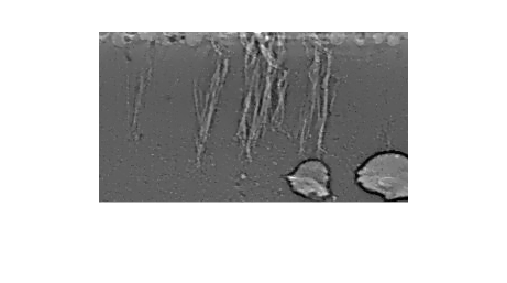

%Generation of K means centroid
%shadow = imread("S05.jpg");
figure
  im=imread("Separation 1.jpg");
  img1=rgb2gray(im);
  %crop the video and greyscale it
  imc=imcrop(im,[  678.5100  295.5100  280 154.9800]);% The dimention of the new video
  img=rgb2gray(imc);
  %enhance the image
S05=localcontrast(img,0.1,-1);
%S05=rgb2gray(imread("S05.jpg"));
imshow(S05)

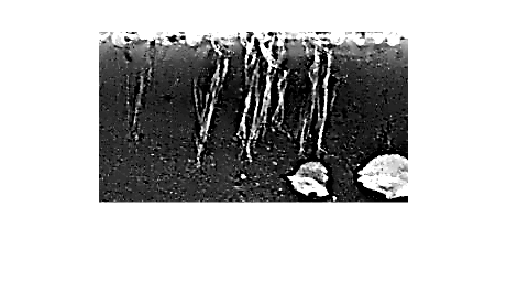

S05C=imadjust(S05,[0.34 0.51],[0 1]);
imshow(S05C)

  [r,c]=size(S05C);
  %add a mask to darken top white area
  clear m
  m(r,c)=zeros;
  z=mean(S05C(:,1));
  for i=1:r
      y=mean(S05C(i,:));
      if z/y>1
          m(i,:)=1;
      else
          m(i,:)=60/y;
      end
  end
  xml=imrotate(uint8(double(S05C).*m),0);
  %canny custom edge operation
  Ixxx=xml;
  BW1 = edge(xml,'Canny',0.19);
  test1=Ixxx+uint8(BW1)*255;
  tm=medfilt2(test1(:,:,1));
  LR=(tm);
  I1= im2bw(LR,0.394);
  I3GAM = bwareaopen(I1, 9);
  I3ER=I3GAM-BW1;
  I3ER2=I3ER>0;
  IXX3=(bwareaopen(I3ER2,3));
  imshow(IXX3)
%segment and quantify
X12= (bwlabel(IXX3));
blobs=regionprops(X12,'all');
blobsT=struct2table(blobs)

blobsT = 95×30 table
    Area        Centroid                  BoundingBox                                                          SubarrayIdx                                                 MajorAxisLength    MinorAxisLength    Eccentricity    Orientation     ConvexHull       ConvexImage      ConvexArea    Circularity        Image          FilledImage      FilledArea    EulerNumber      Extrema       EquivDiameter    Solidity    Extent     PixelIdxList       PixelList      Perimeter    PerimeterOld    MaxFeretDiameter    MaxFeretAngle    MaxF

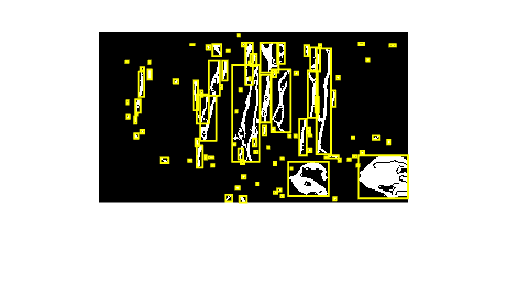

for i=1:length(blobs)
% Draw a rectangle around each blob
rectangle('Position', blobs(i).BoundingBox, 'EdgeColor', 'y','LineWidth',1);
% Draw crosshair at center of each blob
c = blobs(i).Centroid; % Get centroid of blob
%line([c(1)-5 c(1)+5], [c(2) c(2)], 'Color', 'g','LineWidth',1);
%line([c(1) c(1)], [c(2)-5 c(2)+5], 'Color', 'g','LineWidth',1);
end


%tsne kmeans ******
clear xyx k means
blobt=struct2table(blobs);
for j=1:length(blobs)
xyx(j,1)=blobt.MajorAxisLength(j,1)/blobt.MinorAxisLength(j,1);
xyx(j,3)=blobt.MajorAxisLength(j,1)-blobt.MinorAxisLength(j,1);
end
xyx(:,2)=blobt.Eccentricity;
xyx(:,4)=blobt.Circularity;
xyx(:,6)=blobt.Centroid(:,2);
xyx(:,5)=blobt.Orientation;
xyx(:,7)=blobt.ConvexArea; %avoid
xyx(:,8)=1:length(blobs);

y=tsne(xyx(:,1:6),"Standardize",true);
y(:,3)=1:length(blobs);
rng(1) % For reproducibility
%rng(3)
stream = RandStream('mlfg6331_64');  % Random number stream
options = statset('UseParallel',1,'UseSubstreams',1,'Streams',stream);
tic; % Start stopwatch timer
[idx1,C23,sumd,D] = kmeans(y(:,1:2),2,'Options',options,'MaxIter',10000,'Display','final','Replicates',3);

Replicate 3, 3 iterations, total sum of distances = 639.266.
Replicate 1, 4 iterations, total sum of distances = 639.266.
Replicate 2, 3 iterations, total sum of distances = 640.878.
Best total sum of distances = 639.266


toc % Terminate stopwatch timer

Elapsed time is 0.042186 seconds.


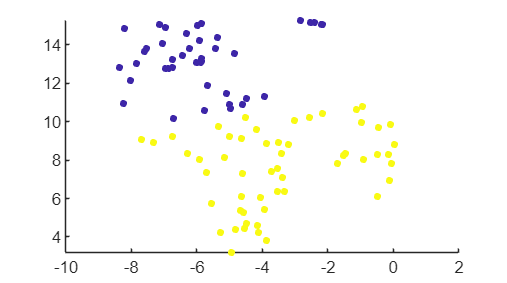

%[idx1, C] = kmeans(y(:,1:2), 3 ,'dist', 'sqEuclidean','start','plus');
scatter(y(:,1),y(:,2),15, idx1, 'filled')

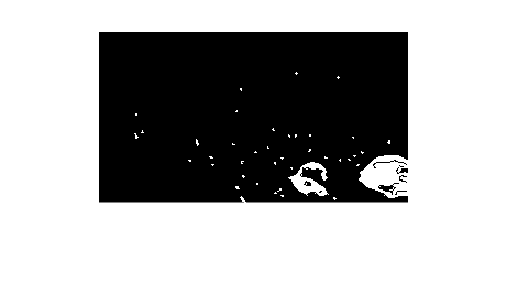

y12=[y(idx1==1,3)];
regionIm = false(size(X12));
regionIm2=false(size(X12));
for i=1:length(y12)
       j=y12(i,1);
       regionIm(blobs(j).PixelIdxList) = true;
       regionIm(blobs(j).PixelIdxList);     
end

AreaMLA=sum(sum(regionIm))

y22=[y(idx1==2,3)];
for i=1:length(y22)
       j=y22(i,1);
       regionIm2(blobs(j).PixelIdxList) = true;
       regionIm2(blobs(j).PixelIdxList);     
end

AreaMLA2=sum(sum(regionIm2))

%imshow(regionIm)
%areaTA=sum(sum(regionIm))
Fin=uint8(255*regionIm);
imshow(Fin)

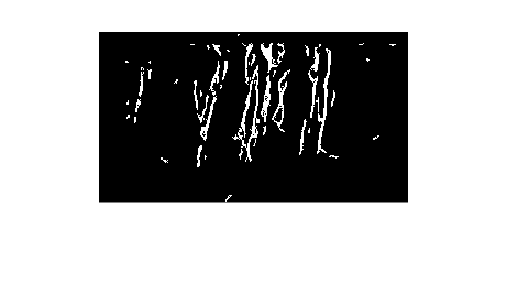

imshow(regionIm2)

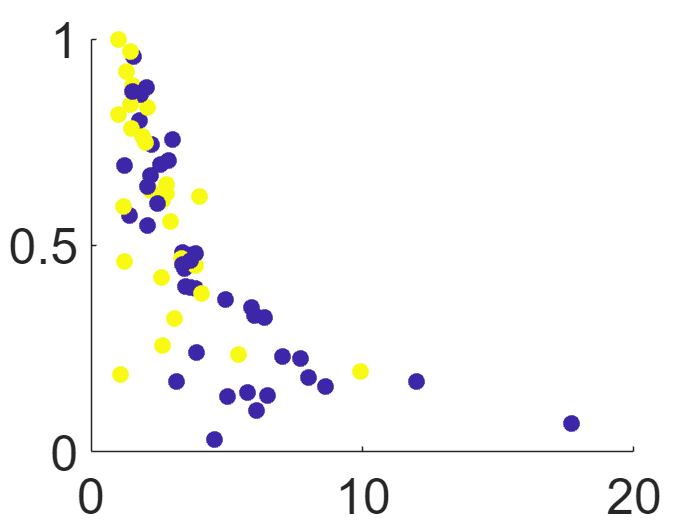

figure
scatter(xyx(:,1),xyx(:,4),100, idx1, 'filled')
fontsize(30,"points")

%1st run
figure
vid1=VideoReader('Result of s07_C001H001S0019.avi');
n=vid1.NumFrames;
writerObj1 = VideoWriter('Regular V1-crop videox.avi');
writerObj1.FrameRate = 4;
firstFrame = read(vid1,n);
vid1

imshow(firstFrame)
[J,rect] = imcrop(firstFrame);
imshow(J)

rect

%2nd run
open(writerObj1);

Unrecognized function or variable 'writerObj1'.

for i=1:n
  im=read(vid1,i);
  img1=rgb2gray(im);
  %crop the video and greyscale it
  imc=imcrop(im,[  678.5100  295.5100  280 154.9800]);% The dimention of the new video
  img=rgb2gray(imc);
  %enhance the image
  S05=localcontrast(img,0.1,-1);
 
  S05C=imadjust(S05,[0.34 0.51],[0 1]);

  [r,c]=size(S05C);
  %add a mask to darken top white area
  clear m
  m(r,c)=zeros;
  z=mean(S05C(:,1));
  for i=1:r
      y=mean(S05C(i,:));
      if z/y>1
          m(i,:)=1;
      else
          m(i,:)=60/y;
      end
  end
  xml=imrotate(uint8(double(S05C).*m),0);
  %canny custom edge operation
  Ixxx=xml;
  BW1 = edge(xml,'Canny',0.19);
  test1=Ixxx+uint8(BW1)*255;
  tm=medfilt2(test1(:,:,1));
  LR=(tm);
  I1= im2bw(LR,0.393);
  I3GAM = bwareaopen(I1, 9);
  I3ER=I3GAM-BW1;
  I3ER2=I3ER>0;
  IXX3=(bwareaopen(I3ER2,3));
%segment and quantify
X12= (bwlabel(IXX3));
blobs=regionprops(X12,'all');
blobsT=struct2table(blobs);
for i=1:length(blobs)
% Draw a rectangle around each blob
rectangle('Position', blobs(i).BoundingBox, 'EdgeColor', 'y','LineWidth',1);
% Draw crosshair at center of each blob
c = blobs(i).Centroid; % Get centroid of blob
%line([c(1)-5 c(1)+5], [c(2) c(2)], 'Color', 'g','LineWidth',1);
%line([c(1) c(1)], [c(2)-5 c(2)+5], 'Color', 'g','LineWidth',1);
end

%tsne kmeans ******
clear xyx k means
blobt=struct2table(blobs);
for j=1:length(blobs)
xyx(j,1)=blobt.MajorAxisLength(j,1)/blobt.MinorAxisLength(j,1);
xyx(j,3)=blobt.MajorAxisLength(j,1)-blobt.MinorAxisLength(j,1);
end
xyx(:,2)=blobt.Eccentricity;
xyx(:,4)=blobt.Circularity;
xyx(:,6)=blobt.Centroid(:,2);
xyx(:,5)=blobt.Orientation;
xyx(:,7)=blobt.ConvexArea; %avoid
xyx(:,8)=1:length(blobs);

y=tsne(xyx(:,1:6),"Standardize",true);
y(:,3)=1:length(blobs);
% % rng('default') % For reproducibility
% % %rng(3)

% % stream = RandStream('mlfg6331_64');  % Random number stream
% % options = statset('UseParallel',1,'UseSubstreams',1,'Streams',stream);
% % tic; % Start stopwatch timer
% % [idx,C,sumd,D] = kmeans(y(:,1:2),2,'Options',options,'MaxIter',10000,'Display','final','Replicates',10);
%toc % Terminate stopwatch timer

%[idx, C] = kmeans(y(:,1:2), 3 ,'dist', 'sqEuclidean','start','plus');

[~,idx] = pdist2(C23,xyx(:,1:6),'euclidean','Smallest',1);
scatter(y(:,1),y(:,2),15, idx, 'filled')
y12=[y(idx==1,3)];
regionIm = false(size(X12));
regionIm2=false(size(X12));
for i=1:length(y12)
       j=y12(i,1);
       regionIm(blobs(j).PixelIdxList) = true;
       regionIm(blobs(j).PixelIdxList);     
end

AreaMLA=sum(sum(regionIm))

y22=[y(idx==2,3)];
for i=1:length(y22)
       j=y22(i,1);
       regionIm2(blobs(j).PixelIdxList) = true;
       regionIm2(blobs(j).PixelIdxList);     
end

AreaMLA2=sum(sum(regionIm2))

%imshow(regionIm)
%areaTA=sum(sum(regionIm))

  %[a,b]=size(img1);
  %Fin=imresize(Fin,[a,b]);
  writeVideo(writerObj1,Fin);  
    subplot(1,2,1)
    imshow(im)
    subplot(1,2,2)
    imshow(Fin)
   
   
end
close(writerObj1)


%2nd run
open(writerObj1);
for i=1:n
  im=read(vid1,i);
  img1=rgb2gray(im);
  %crop the video and greyscale it
  imc=imcrop(im,[  678.5100  295.5100  280 154.9800]);% The dimention of the new video
  img=rgb2gray(imc);
  Fin=img;
  writeVideo(writerObj1,Fin);  
    subplot(1,2,1)
    imshow(im)
    subplot(1,2,2)
    imshow(Fin)
   
   
end
close(writerObj1)